# Getting Started with LiDAR Point Clouds

In this demonstration, you'll learn how to import and process point clouds in MATLAB. For this series, we have collected point clouds from a simulated environment with a LiDAR attached to a car driving in a parking lot. The scene was simulated entirely using [Simulink 3D Animation](https://www.mathworks.com/help/driving/unreal-engine-scenario-simulation.html). The GIF below shows a short camera clip from the simulation. 

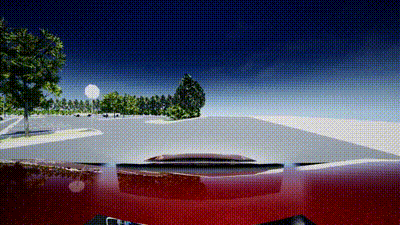

The typical workflow when working with point cloud data is given below. 

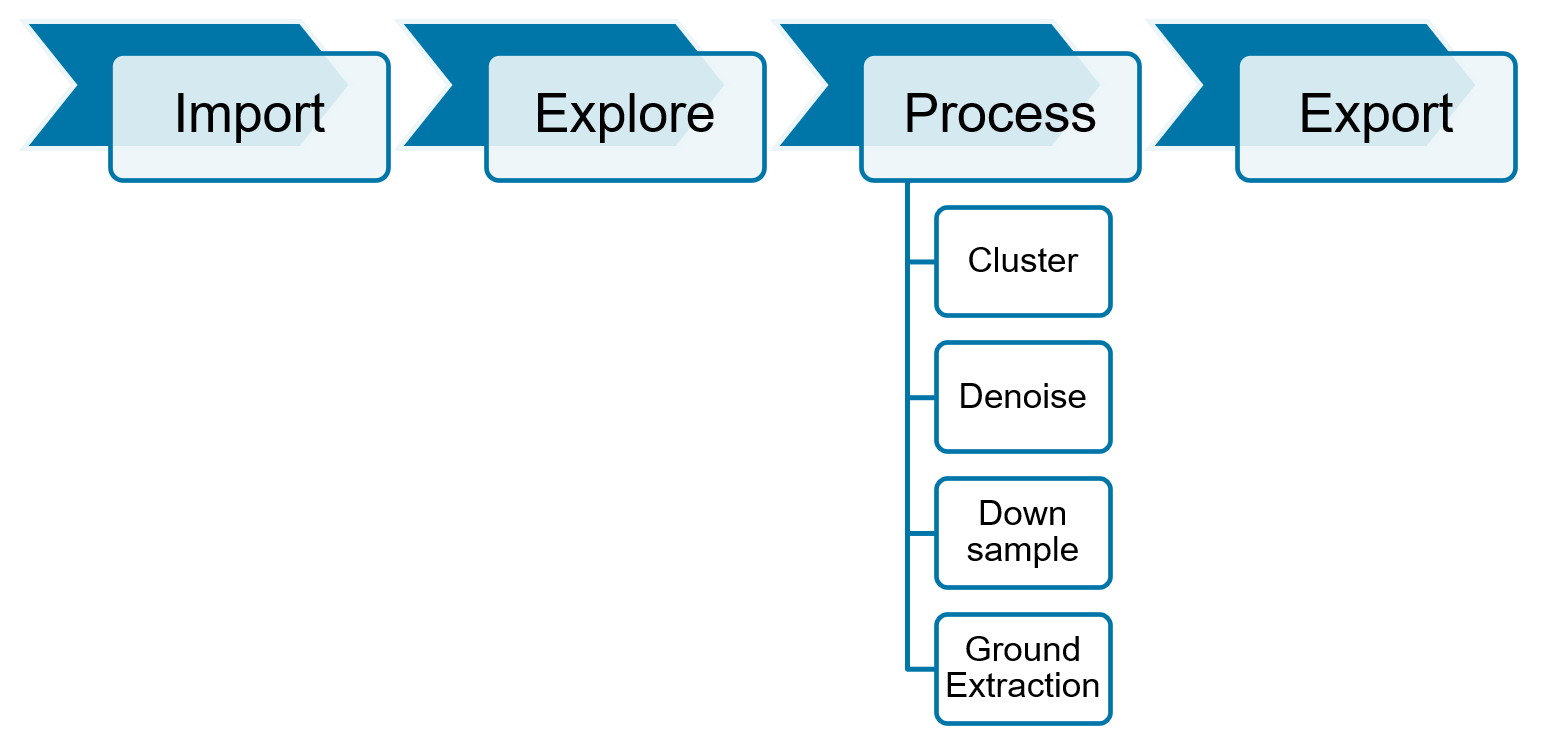

We'll follow the same structure and show how you can do the steps in 2 ways:

- Using the Lidar Viewer App

- Programmatically

## Using the Lidar Viewer App

The Lidar Viewer app lets you import, view, and manipulate point clouds interactively. This is a great tool to quickly visualize the data, and you can open it from the 'Apps' tab

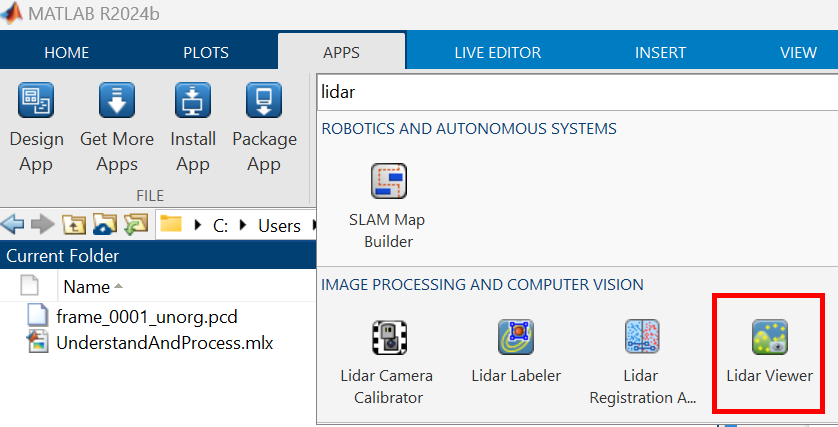

Or by using the `lidarViewer` function.

lidarViewer

To get started, load the 'parkingLot' folder into the app

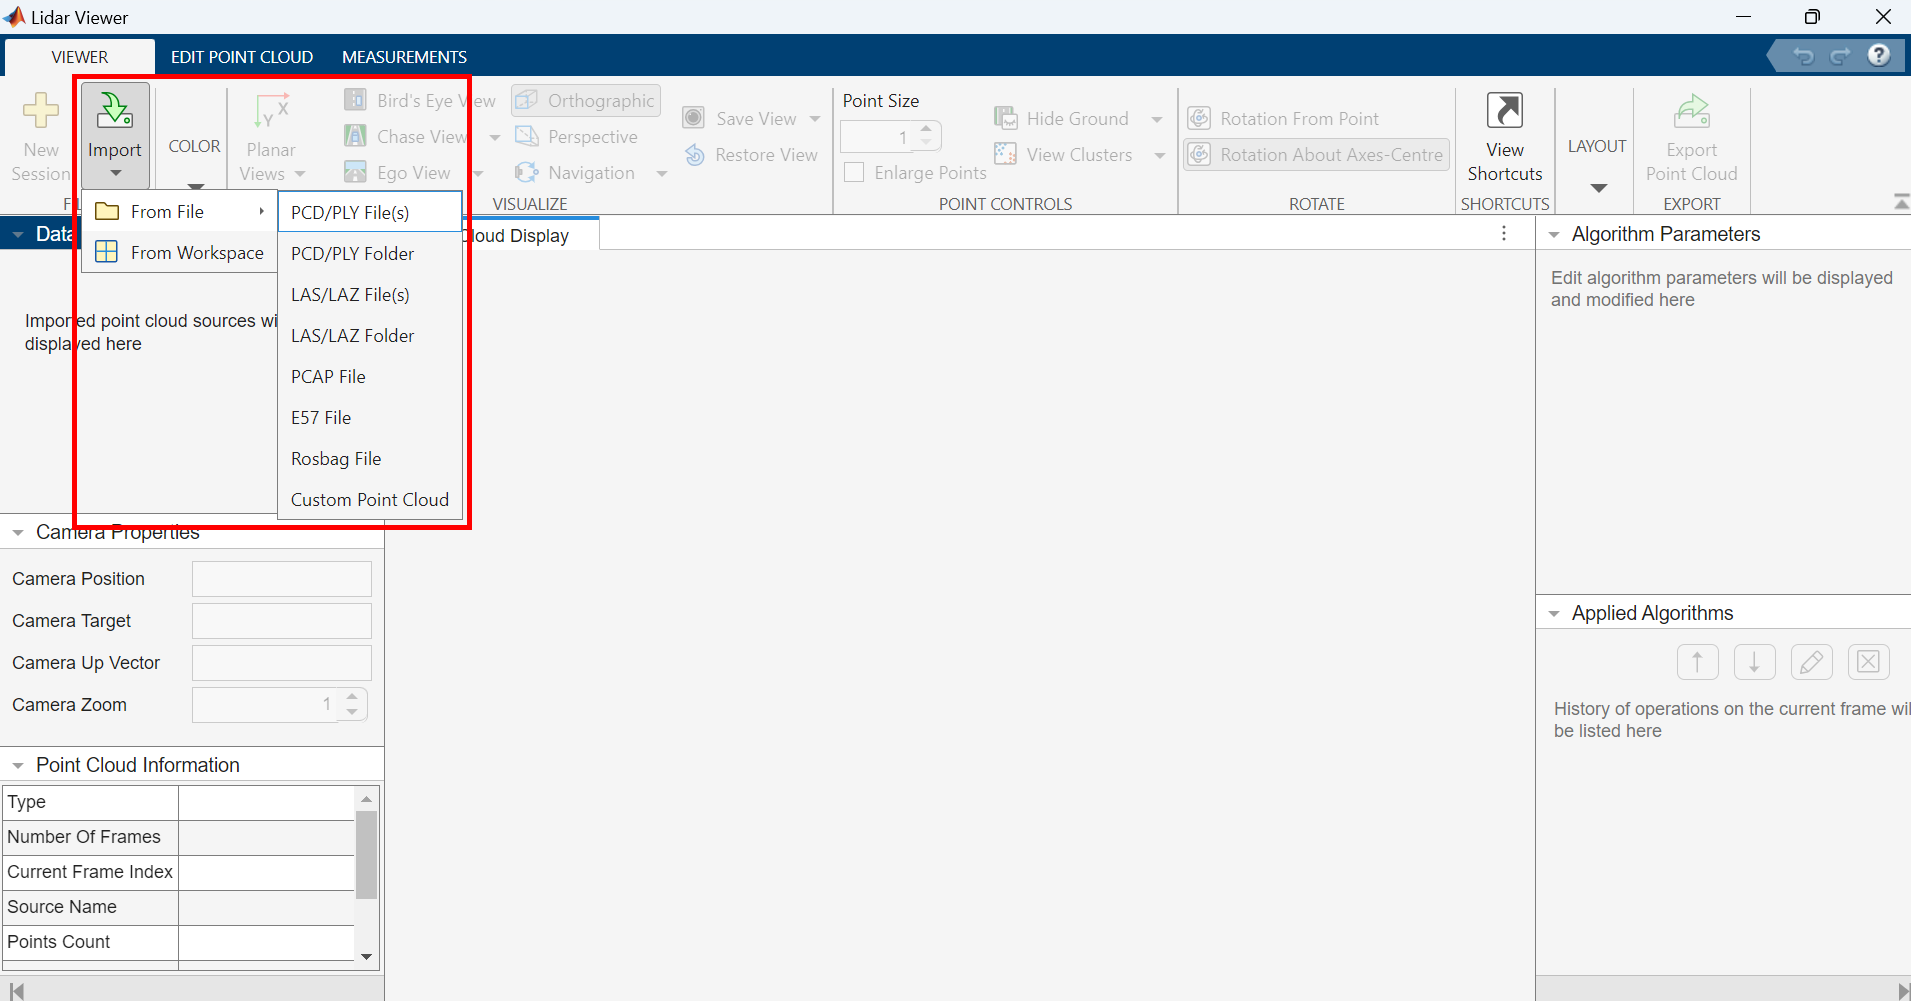

You can adjust the size of the points to make the cloud easier to view

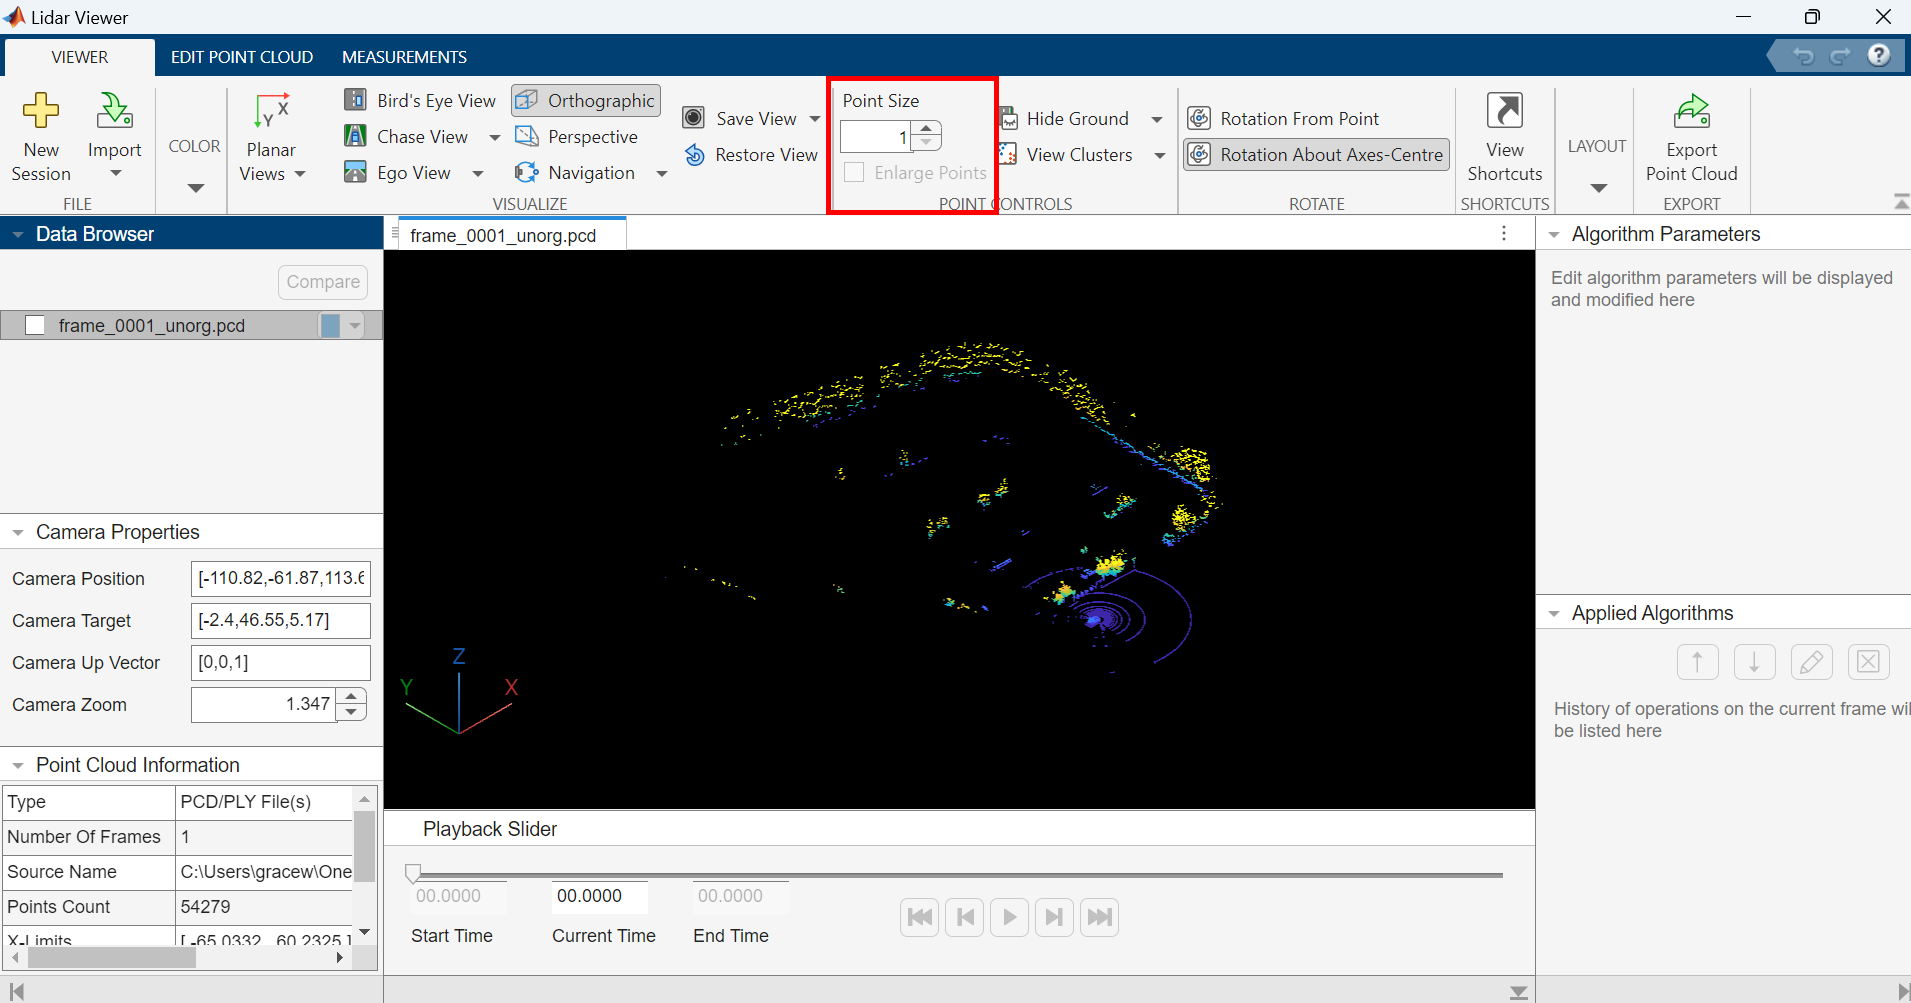

To explore the point cloud, you can use the options on the 'Visualize' tab or use your mouse to zoom, pan, and rotate

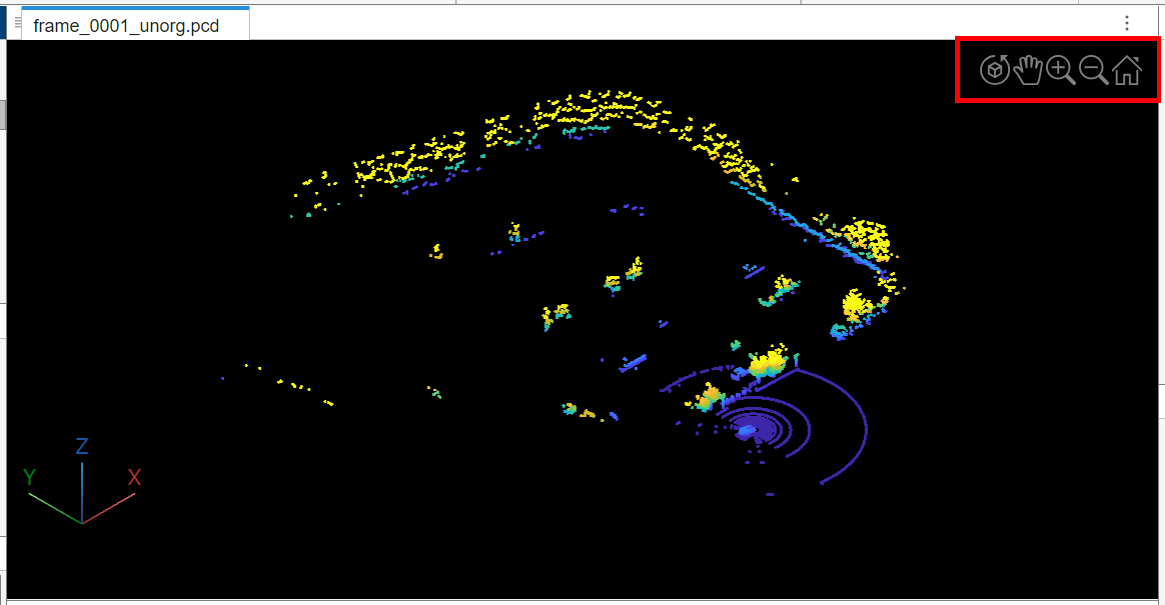

You can also use the app to perform clustering, which attempts to separate the points into groups (or "clusters") where each cluster represents one object. 

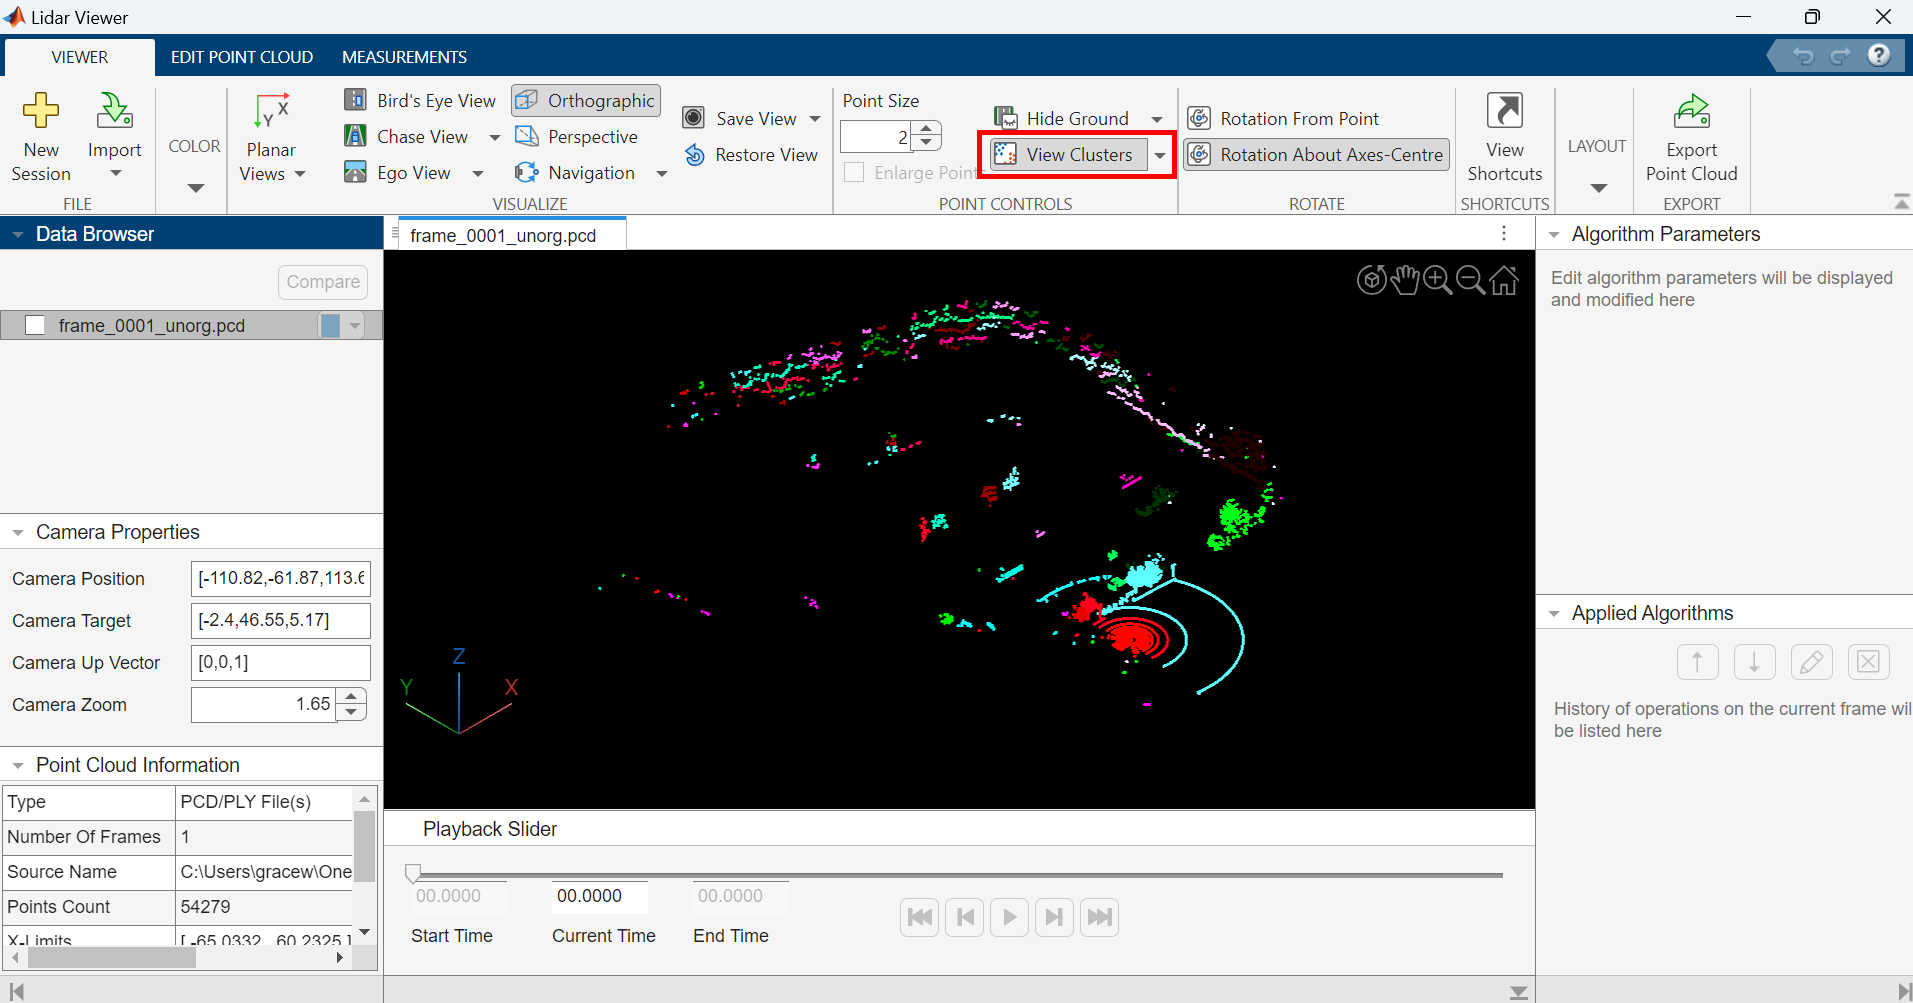

You can modify the point cloud to only keep the data you are interested in and to reduce the size of each point cloud, which makes working with them faster. This can be done through ground removal, denoising, and downsampling on the 'Edit Point Cloud' tab. 

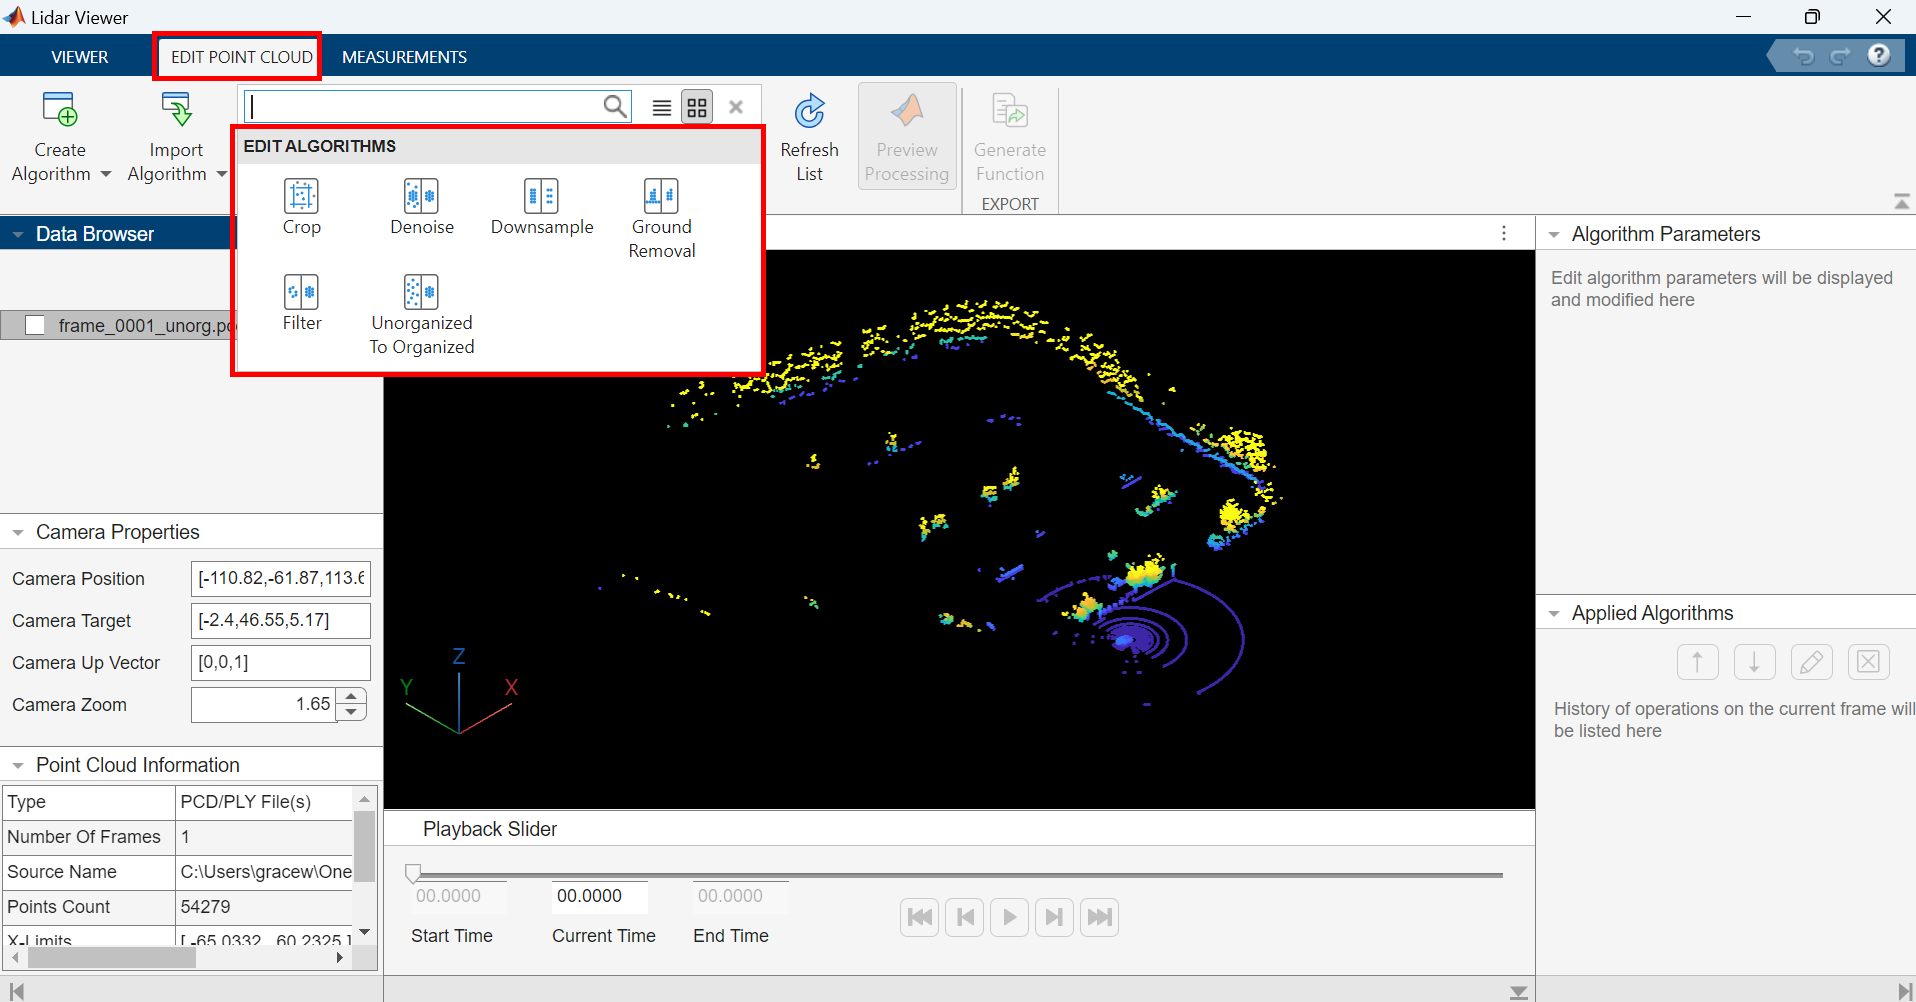

When you are done processing your data, you can export the modified point clouds 

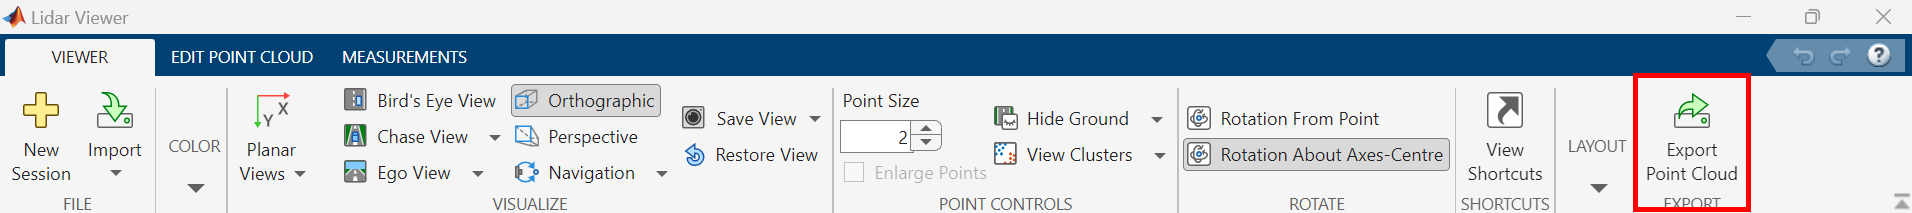

Or you can generate code files that will modify additional point clouds in the same way you modified the current point clouds

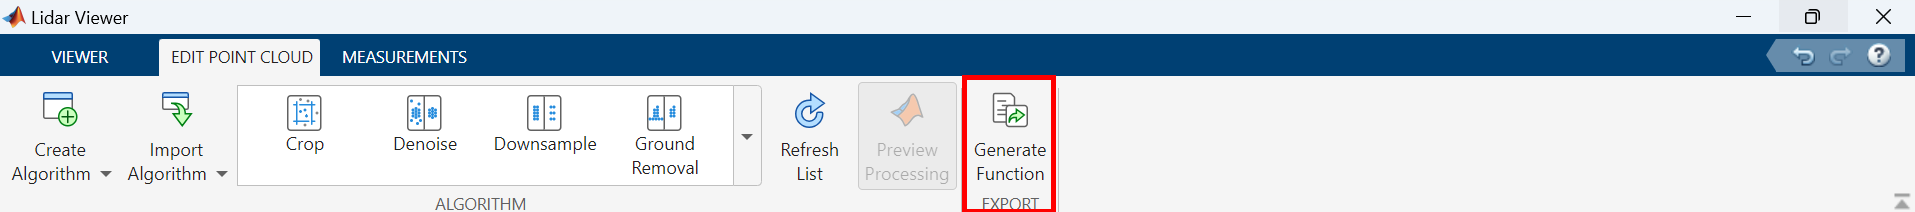

## Programmatic approach for processing LiDAR data

The previous section demonstrated how you can use the LiDAR Viewer App to interactively work with point clouds. This section covers much of the same topics but in a programmatic way, which provides an alternative approach when working with large dataset.

You can import LiDAR point cloud data using the `pcread` function

unorgPtCld = pcread('../parkingLot/frame_0001.pcd')

unorgPtCld =   pointCloud with properties:

     Location: [32×1083×3 single]
        Count: 34656
      XLimits: [-14.0101 106.3789]
      YLimits: [-54.9892 71.8594]
      ZLimits: [-0.5157 11.1050]
        Color: []
       Normal: []
    Intensity: [32×1083 single]


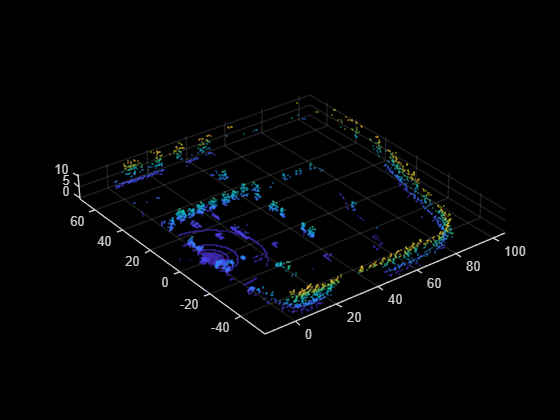

pcshow(unorgPtCld)

### Organizing

Point clouds are stored in two different ways - organized and unorganized. Organized point clouds have a grid-like structure with data divided into rows and columns. The data is divided according to the spatial relationships between the points. These are usually produced by stereo cameras or RGB-D cameras. Unorganized point clouds consists of a single stream of 3-D coordinates, each representing a single point. Most lidar sensors produce unorganized clouds, but it's easier to work with organized clouds. The `pcorganize` function lets you convert the data from an unorganized cloud to an organized one. 

verticalResolution = 32; 
verticalFoV = [20, -20]; 
horizontalResolution = 2250;
params = lidarParameters(verticalResolution,verticalFoV, horizontalResolution);
ptCld = pcorganize(unorgPtCld,params)

ptCld =   pointCloud with properties:

     Location: [32×2250×3 single]
        Count: 72000
      XLimits: [-14.0101 106.3789]
      YLimits: [-54.9892 71.8594]
      ZLimits: [-0.5157 11.1050]
        Color: []
       Normal: []
    Intensity: [32×2250 single]


If you view the point cloud, notice that this doesn't change how it is displayed. It just reorganizes how the data is stored, as you can see if you compare the "Location" property of ptCld with the "Location" property of unorgPtCld. 

pcshow(ptCld)

Check out this [documentation](https://www.mathworks.com/help/lidar/ug/organized-and-unorganized-point-clouds.html) to learn more about organized and unorganized point clouds.

### Denoising

Sometimes, point clouds can have "noise", or data points that are outliers to what you'd expect to see in your point cloud. Use the `pcdenoise` function to remove or reduce these.The purple dots in the figures below are points that were removed.

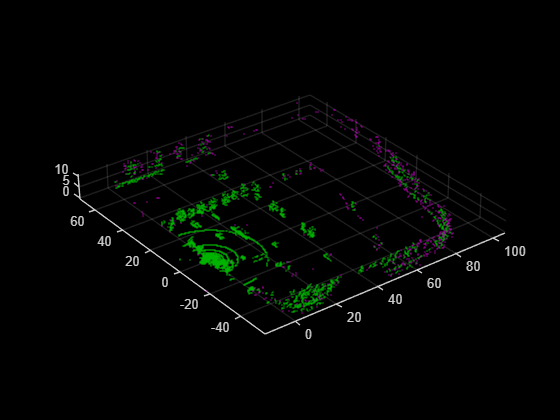

ptCloudDenoise = pcdenoise(ptCld);
figure
pcshowpair(ptCld, ptCloudDenoise)

You can adjust the parameters of the `pcdenoise` function to specify how the function determines outliers. 

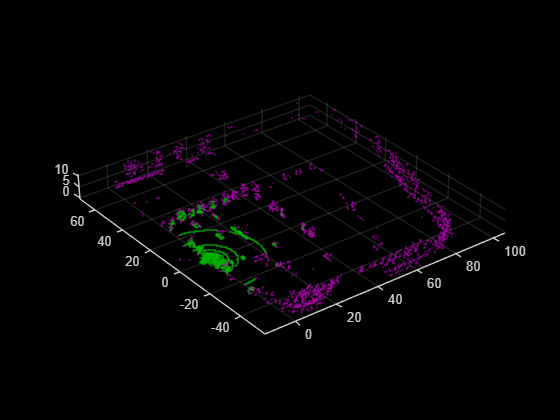

ptCloudDenoise = pcdenoise(ptCld,...
    "NumNeighbors", 20,... % default 4
    "Threshold", 0.05); % default 1
figure
pcshowpair(ptCld, ptCloudDenoise)

### Downsampling

Depending on your LiDAR and the environment you collected data in, you may have a lot of data points, which can lead to slower computaton. Use the `pcdownsample` function to make your point cloud less dense through downsampling. 

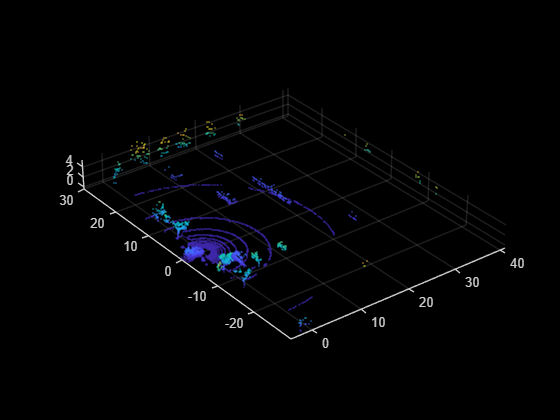

ptCloudDownSampled = pcdownsample(ptCloudDenoise,'random',0.60);
pcshow(ptCloudDownSampled)

Now we have a point cloud that still shows the same objects, but takes less memory. Use `pcshowpair` to view which data points were removed (purple) and which stayed (green). 

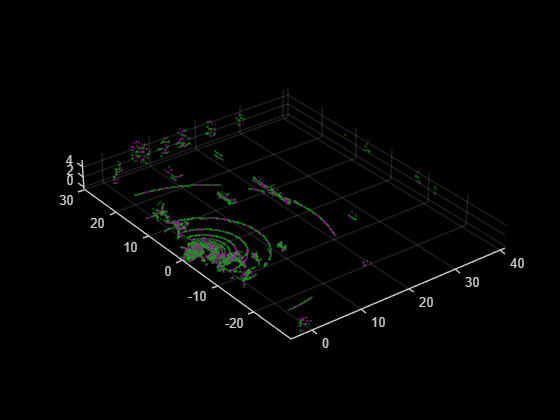

pcshowpair(ptCloudDenoise, ptCloudDownSampled)

### Ground Extraction

This point cloud inclues many data points for the ground, but you may not need to care about the ground. You can remove these data points using a few different functions, such as `pcfitplane` or `segmentGroundFromLidarData.`Here, let's use `segmentgroundsmrf`.

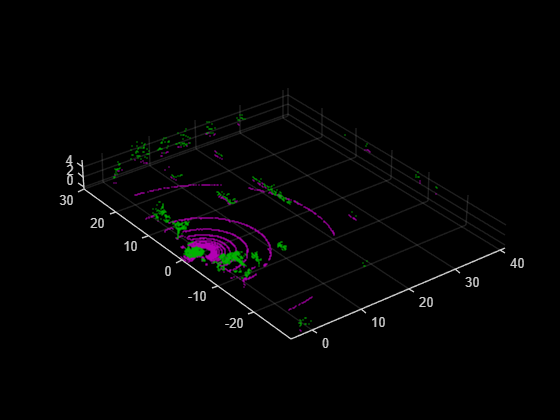

[groundPtsIdx,nonGroundPtCloud,groundPtCloud] = segmentGroundSMRF(ptCloudDownSampled, ...
    ElevationThreshold=0.1, ...
    MaxWindowRadius=8);
pcshowpair(groundPtCloud,nonGroundPtCloud)

### Clustering

Extracting and removing the ground plane often makes it easier to perform clustering. Clustering helps to segment point cloud into different groups based on the distance between points, resulting in clusters of points that represent individual objects. Use `pcsegdist` to cluster a point cloud based on the distance of the points.

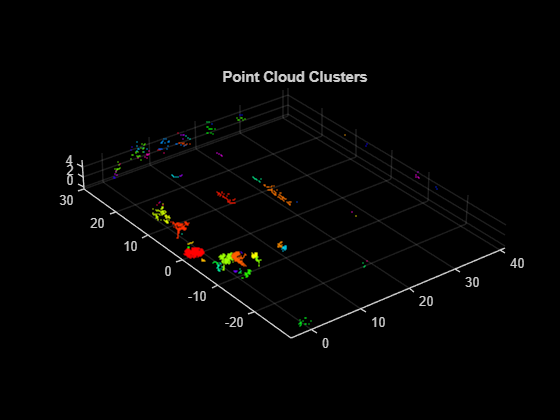

distThreshold = 0.8; 
[labels,numClusters] = pcsegdist(nonGroundPtCloud,distThreshold);

clusterAx = pcshow(nonGroundPtCloud.Location,labels);
clusterAx.XLim = ptCloudDownSampled.XLimits;
clusterAx.YLim = ptCloudDownSampled.YLimits;
colormap([hsv(numClusters);[0 0 0]])
title('Point Cloud Clusters')